strucFileName = "ROCOFtest"

strucFileName = "ROCOFtest"

load("sim_data_" + strucFileName + ".mat","struc_powers","struc_DClinkCaps","struc_freq","struc_RMSvoltcurr","Tend",'-mat');

Tend = 10

Tend = 12


t_freq = struc_freq.time;
freq = struc_freq.signals.values;

t_DC = struc_DClinkCaps.time ;
DC_voltage = struc_DClinkCaps.signals(1).values;
Cap_curr = struc_DClinkCaps.signals(2).values;

t_RMSv = struc_RMSvoltcurr.time;
v_LOAD = struc_RMSvoltcurr.signals(1).values(:,1);
v_GRID = struc_RMSvoltcurr.signals(1).values(:,4);
v_GFM = struc_RMSvoltcurr.signals(1).values(:,7);

t_powers = struc_powers.time;
p_LOAD = struc_powers.signals(1).values(:,1);
p_GRID = struc_powers.signals(1).values(:,2);
p_GFM = struc_powers.signals(1).values(:,3);
% p_GFM_ref = struc_powers.signals(1).values(:,4);

## Visualize



plotTitle = "ROCOFtest"

plotTitle = "ROCOFtest"

figName = plotTitle;


## RMS Voltage

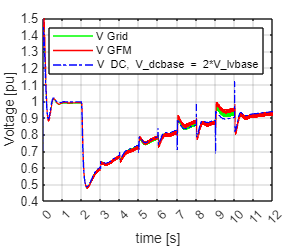


figure('Name','Voltages'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
hold on
grid on
box on

plot(t_RMSv,v_GRID,'g-',LineWidth=1);
plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
plot(t_DC, DC_voltage/(2*sqrt(2)*690/sqrt(3)),'b-.', LineWidth=1)
% title(plotTitle,Interpreter="tex")

axis([0 Tend 0.4 1.5])
legend('V Grid', 'V GFM','V DC, V\_{dcbase} = 2*V\_{lvbase}') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('Voltage [pu]')
ay = gca;
ay.YTick = 0.4:0.1:1.5;
ay.XTick =0:1:Tend;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "voltages"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "voltages"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Powers

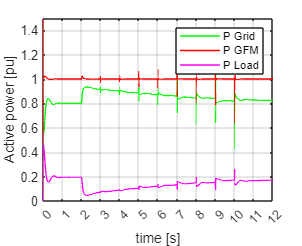

figure('Name','Active_Power'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
hold on
box on
grid on

plot(t_powers,-1.*p_GRID,'g-',LineWidth=1);
plot(t_powers,p_GFM,'r-',LineWidth=1);
plot(t_powers,p_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([0 Tend 0 1.5])
legend('P Grid', 'P GFM','P Load') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('Active power [pu]')
ay = gca;
ay.YTick = 0:0.2:1.5;
ay.XTick =0:1:Tend;
hold off


set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "Active_Power"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "Active_Power"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Frequency

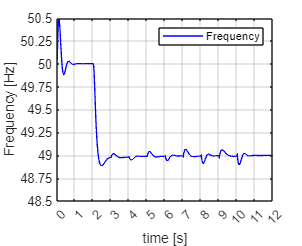


figure('Name','Freuqency'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
box on
hold on
grid on

plot(t_freq,freq,'b-',LineWidth=1)
legend('Frequency')
axis([0 Tend 48.5 50.5])
xlabel('time [s]')
ylabel('Frequency [Hz]')
ay = gca;

ay.YTick = 48.5:0.25:50.5;
ay.XTick =0:1:Tend;
hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "Frequency"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "Frequency"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Reactive

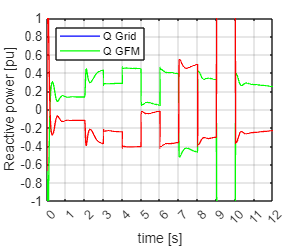

    figure('Name','Reactive_Power'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])

    q_LOAD = struc_powers.signals(2).values(:,1);
    q_GRID = struc_powers.signals(2).values(:,2);
    q_GFM = struc_powers.signals(2).values(:,3);
      

hold on
    grid on
    box on
    
    % plot(t,q_GFM_ref,'g-',LineWidth=1);
    plot(t_powers,q_GRID,'g-',LineWidth=1);
    plot(t_powers,q_GFM,'r-',LineWidth=1);

axis([0 Tend -1 1])
    ay = gca;
ay.YTick = -1:0.2:1;
ay.XTick =0:1:Tend;
hold off

    legend( 'Q Grid','Q GFM' ,Location='northwest') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
    xlabel('time [s]')
    ylabel('Reactive power [pu]')

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "Reactive_Power"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "Reactive_Power"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)